# Punto 3

##  2.Constrained Optimization

#### 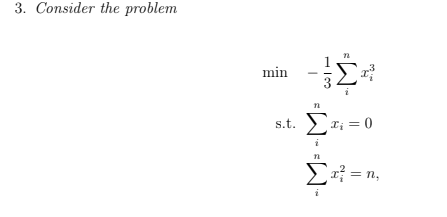

El objetivo de este problema es optimizar una función bajo ciertas restricciones, utilizando el método de Lagrange y las condiciones de Karush-Kuhn-Tucker (KKT). La función objetivo se define como una suma cúbica de las variables xi.

% Función objetivo
n=4;

% Declarar las variables simbólicas
syms x1 x2 x3 x4 lambda mu real;

x = [x1; x2; x3; x4]; 
f3 = -(1/3) * sum(x.^3)

$$f3 = -\frac{{x_{1}}^{3}}{3}-\frac{{x_{2}}^{3}}{3}-\frac{{x_{3}}^{3}}{3}-\frac{{x_{4}}^{3}}{3}$$


% Restricciones
h1 = sum(x);            % Primera restricción: suma de xi = 0
h2 = sum(x.^2) - n;     % Segunda restricción: suma de xi^2 = n


Estas restricciones se imponen al Lagrangiano, que es una combinación de la función objetivo y las restricciones multiplicadas por los multiplicadores de Lagrange λ y μ, respectivamente.

Luego, se calcula el gradiente del Lagrangiano respecto a las variables xi y se resuelven las ecuaciones correspondientes para obtener los valores de xi, λ y  que satisfacen las condiciones de KKT. Después, se evalúan estas soluciones en la Hessiana del Lagrangiano para clasificar los puntos como máximos, mínimos o puntos silla.

% Lagrangiano
L = f3 + lambda * h1 + mu * h2;

% Primera condición KKT: gradiente de L respecto a x_i
disp('Primera condición KKT (gradiente de L):');

Primera condición KKT (gradiente de L):


grad_L = gradient(L, x)

% Resolver las ecuaciones del gradiente respecto a x_i
eq1 = grad_L == 0

$$eq1 = \left(\begin{array}{c} -{x_{1}}^{2}+2\,\mu \,x_{1}+\lambda =0\\ -{x_{2}}^{2}+2\,\mu \,x_{2}+\lambda =0\\ -{x_{3}}^{2}+2\,\mu \,x_{3}+\lambda =0\\ -{x_{4}}^{2}+2\,\mu \,x_{4}+\lambda =0 \end{array}\right)$$


% Impongo las restricciones
eq2 = h1 == 0;
eq3 = h2 == 0;

% Resolver el sistema de ecuaciones
disp('Resolviendo el sistema KKT...');

Resolviendo el sistema KKT...


vars = [x; lambda; mu]; 
solutions = solve([eq1; eq2; eq3], vars, 'Real', true);

% Mostrar las soluciones
disp('Soluciones para x_i, lambda y mu:');

Soluciones para x_i, lambda y mu:


solutions_x = ([solutions.x1, solutions.x2, solutions.x3, solutions.x4]); % x1, x2, ..., xn
lambda_sol = (solutions.lambda);
mu_sol = (solutions.mu);

disp('Soluciones de x:');

Soluciones de x:


disp(solutions_x);

$$\left(\begin{array}{cccc} 1 & 1 & -1 & -1\\ 1 & -1 & 1 & -1\\ -1 & 1 & 1 & -1\\ 1 & -1 & -1 & 1\\ -1 & 1 & -1 & 1\\ -1 & -1 & 1 & 1\\ -\frac{\sqrt{3}}{3} & -\frac{\sqrt{3}}{3} & -\frac{\sqrt{3}}{3} & \sqrt{3}\\ -\frac{\sqrt{3}}{3} & -\frac{\sqrt{3}}{3} & \sqrt{3} & -\frac{\sqrt{3}}{3}\\ -\frac{\sqrt{3}}{3} & \sqrt{3} & -\frac{\sqrt{3}}{3} & -\frac{\sqrt{3}}{3}\\ \sqrt{3} & -\frac{\sqrt{3}}{3} & -\frac{\sqrt{3}}{3} & -\frac{\sqrt{3}}{3}\\ \frac{\sqrt{3}}{3} & \frac{\sqrt{3}}{3} & \frac{\sqrt{3}}{3} & -\sqrt{3}\\ \frac{\sqrt{3}}{3} & \frac{\sqrt{3}}{3} & -\sqrt{3} & \frac{\sqrt{3}}{3}\\ \frac{\sqrt{3}}{3} & -\sqrt{3} & \frac{\sqrt{3}}{3} & \frac{\sqrt{3}}{3}\\ -\sqrt{3} & \frac{\sqrt{3}}{3} & \frac{\sqrt{3}}{3} & \frac{\sqrt{3}}{3} \end{array}\right)$$


disp('Valor de lambda:');

Valor de lambda:


disp(lambda_sol);

$$\left(\begin{array}{c} 1\\ 1\\ 1\\ 1\\ 1\\ 1\\ 1\\ 1\\ 1\\ 1\\ 1\\ 1\\ 1\\ 1 \end{array}\right)$$


disp('Valor de mu:');

Valor de mu:


disp(mu_sol);

$$\left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ \frac{\sqrt{3}}{3}\\ \frac{\sqrt{3}}{3}\\ \frac{\sqrt{3}}{3}\\ \frac{\sqrt{3}}{3}\\ -\frac{\sqrt{3}}{3}\\ -\frac{\sqrt{3}}{3}\\ -\frac{\sqrt{3}}{3}\\ -\frac{\sqrt{3}}{3} \end{array}\right)$$


% Segunda condición KKT: Hessiana del Lagrangiano respecto a x
disp('Hessiana del Lagrangiano:');

Hessiana del Lagrangiano:


Hessian_L = hessian(L, x);
disp(Hessian_L);

$$\left(\begin{array}{cccc} 2\,\mu -2\,x_{1} & 0 & 0 & 0\\ 0 & 2\,\mu -2\,x_{2} & 0 & 0\\ 0 & 0 & 2\,\mu -2\,x_{3} & 0\\ 0 & 0 & 0 & 2\,\mu -2\,x_{4} \end{array}\right)$$

ValoresPro=eig(Hessian_L)

$$ValoresPro = \left(\begin{array}{c} 2\,\mu -2\,x_{1}\\ 2\,\mu -2\,x_{2}\\ 2\,\mu -2\,x_{3}\\ 2\,\mu -2\,x_{4} \end{array}\right)$$


i=0;
for i = 1:length(solutions.mu)
    ValoresPro2=subs(ValoresPro,[x1, x2, x3, x4, mu,lambda],[solutions.x1(i), solutions.x2(i), solutions.x3(i), solutions.x4(i),solutions.mu(i),solutions.lambda(i)])
    % Clasificar según los valores propios
    if all(ValoresPro2 > 0)
        disp('La solución corresponde a un MÍNIMO local.');
    elseif all(ValoresPro2 < 0)
        disp('La solución corresponde a un MÁXIMO local.');
    else
        disp('La solución corresponde a un PUNTO SILLA.');
    end
    i=i+1;
end

$$ValoresPro2 = \left(\begin{array}{c} -2\\ -2\\ 2\\ 2 \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} -2\\ 2\\ -2\\ 2 \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} 2\\ -2\\ -2\\ 2 \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} -2\\ 2\\ 2\\ -2 \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} 2\\ -2\\ 2\\ -2 \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} 2\\ 2\\ -2\\ -2 \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} \frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3} \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} \frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3} \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} \frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3} \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} -\frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3} \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} -\frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3} \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} -\frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3} \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} -\frac{4\,\sqrt{3}}{3}\\ \frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3} \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


$$ValoresPro2 = \left(\begin{array}{c} \frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3}\\ -\frac{4\,\sqrt{3}}{3} \end{array}\right)$$

La solución corresponde a un PUNTO SILLA.


% Verificación de las restricciones para cada solución
for i = 1:size(solutions_x, 1)
    current_solution = double(solutions_x(i, :));
    h1_val = sum(current_solution);           % Suma de x_i
    h2_val = sum(current_solution.^2) - n;   % Suma de x_i^2 - n

    disp(['Solución ', num2str(i), ':']);
    disp(current_solution);
    disp(h1_val);
    disp(h2_val);
end

Solución 1:


     1     1    -1    -1



     0



     0



Solución 2:


     1    -1     1    -1



     0



     0



Solución 3:


    -1     1     1    -1



     0



     0



Solución 4:


     1    -1    -1     1



     0



     0



Solución 5:


    -1     1    -1     1



     0



     0



Solución 6:


    -1    -1     1     1



     0



     0



Solución 7:


   -0.5774   -0.5774   -0.5774    1.7321



     0



  -4.4409e-16



Solución 8:


   -0.5774   -0.5774    1.7321   -0.5774



     0



  -4.4409e-16



Solución 9:


   -0.5774    1.7321   -0.5774   -0.5774



     0



     0



Solución 10:


    1.7321   -0.5774   -0.5774   -0.5774



     0



     0



Solución 11:


    0.5774    0.5774    0.5774   -1.7321



     0



  -4.4409e-16



Solución 12:


    0.5774    0.5774   -1.7321    0.5774



     0



  -4.4409e-16



Solución 13:


    0.5774   -1.7321    0.5774    0.5774



     0



     0



Solución 14:


   -1.7321    0.5774    0.5774    0.5774



     0



     0



## Justificación

En este caso, el análisis realizado a través de la Hessiana nos muestra que las soluciones no corresponden a máximos o mínimos locales, sino que en su mayoría son puntos silla. Esto se debe a las propiedades de la función objetivo y las restricciones impuestas.

- La condición de que las soluciones no correspondan a máximos o mínimos locales se debe a que la función objetivo es una función cúbica, lo que implica que no es una función convexa ni cóncava. En lugar de tener una forma que se pueda clasificar fácilmente como un máximo o mínimo local, la función tiene puntos en los que la curvatura cambia de forma, lo que genera puntos silla.

- La función objetivo tiene una curvatura que no es constante, y las restricciones impuestas (la suma de las variables igual a cero y la suma de sus cuadrados igual a n) configuran un espacio de soluciones que genera puntos donde la curvatura cambia de signo. Estos puntos son considerados puntos silla, ya que en algunas direcciones la función tiene una pendiente positiva y en otras una pendiente negativa.

- Estos puntos silla son soluciones factibles que satisfacen las condiciones de KKT, pero no representan extremos locales, ya que la curvatura de la función cambia en diferentes direcciones.